# Modsim Project 2

## Question

In the winter, people are often told to turn the heat down/off when they leave the house to save energy. However, there is also an argument that leaving the heat on when you leave is more efficient.  This model will seek to explain if there are any scenarios were leaving the heat on could be more energy efficient than turning it off when leaving the house for some amount of time.  Answering this question is important because it could resolve a potential spread of misinformation. In addition, it might help homeowners make more energy conscious decisions about their heating which would benefit their wallets and the environment.

**Learning Objectives**

Olivia

- Learn how to create a good modeling question

- Understand best practices in structuring a thermodynamic model

Rowan

- Want to write my own ODE’s / understand how to generate an equation for a modeling question

## Methodology

### Stock and Flow

To compare the efficiency of turning the heater off vs. leaving it on, a stock and flow model of a house was created.  In this simplified model, the stock is the internal energy of the house. A heater adds energy to the stock while the house loses energy though conduction. When the heater is on, it adds energy at a constant rate (\frac{dU}{dt} = W_{heater}) and when it is off, no heat is added. 

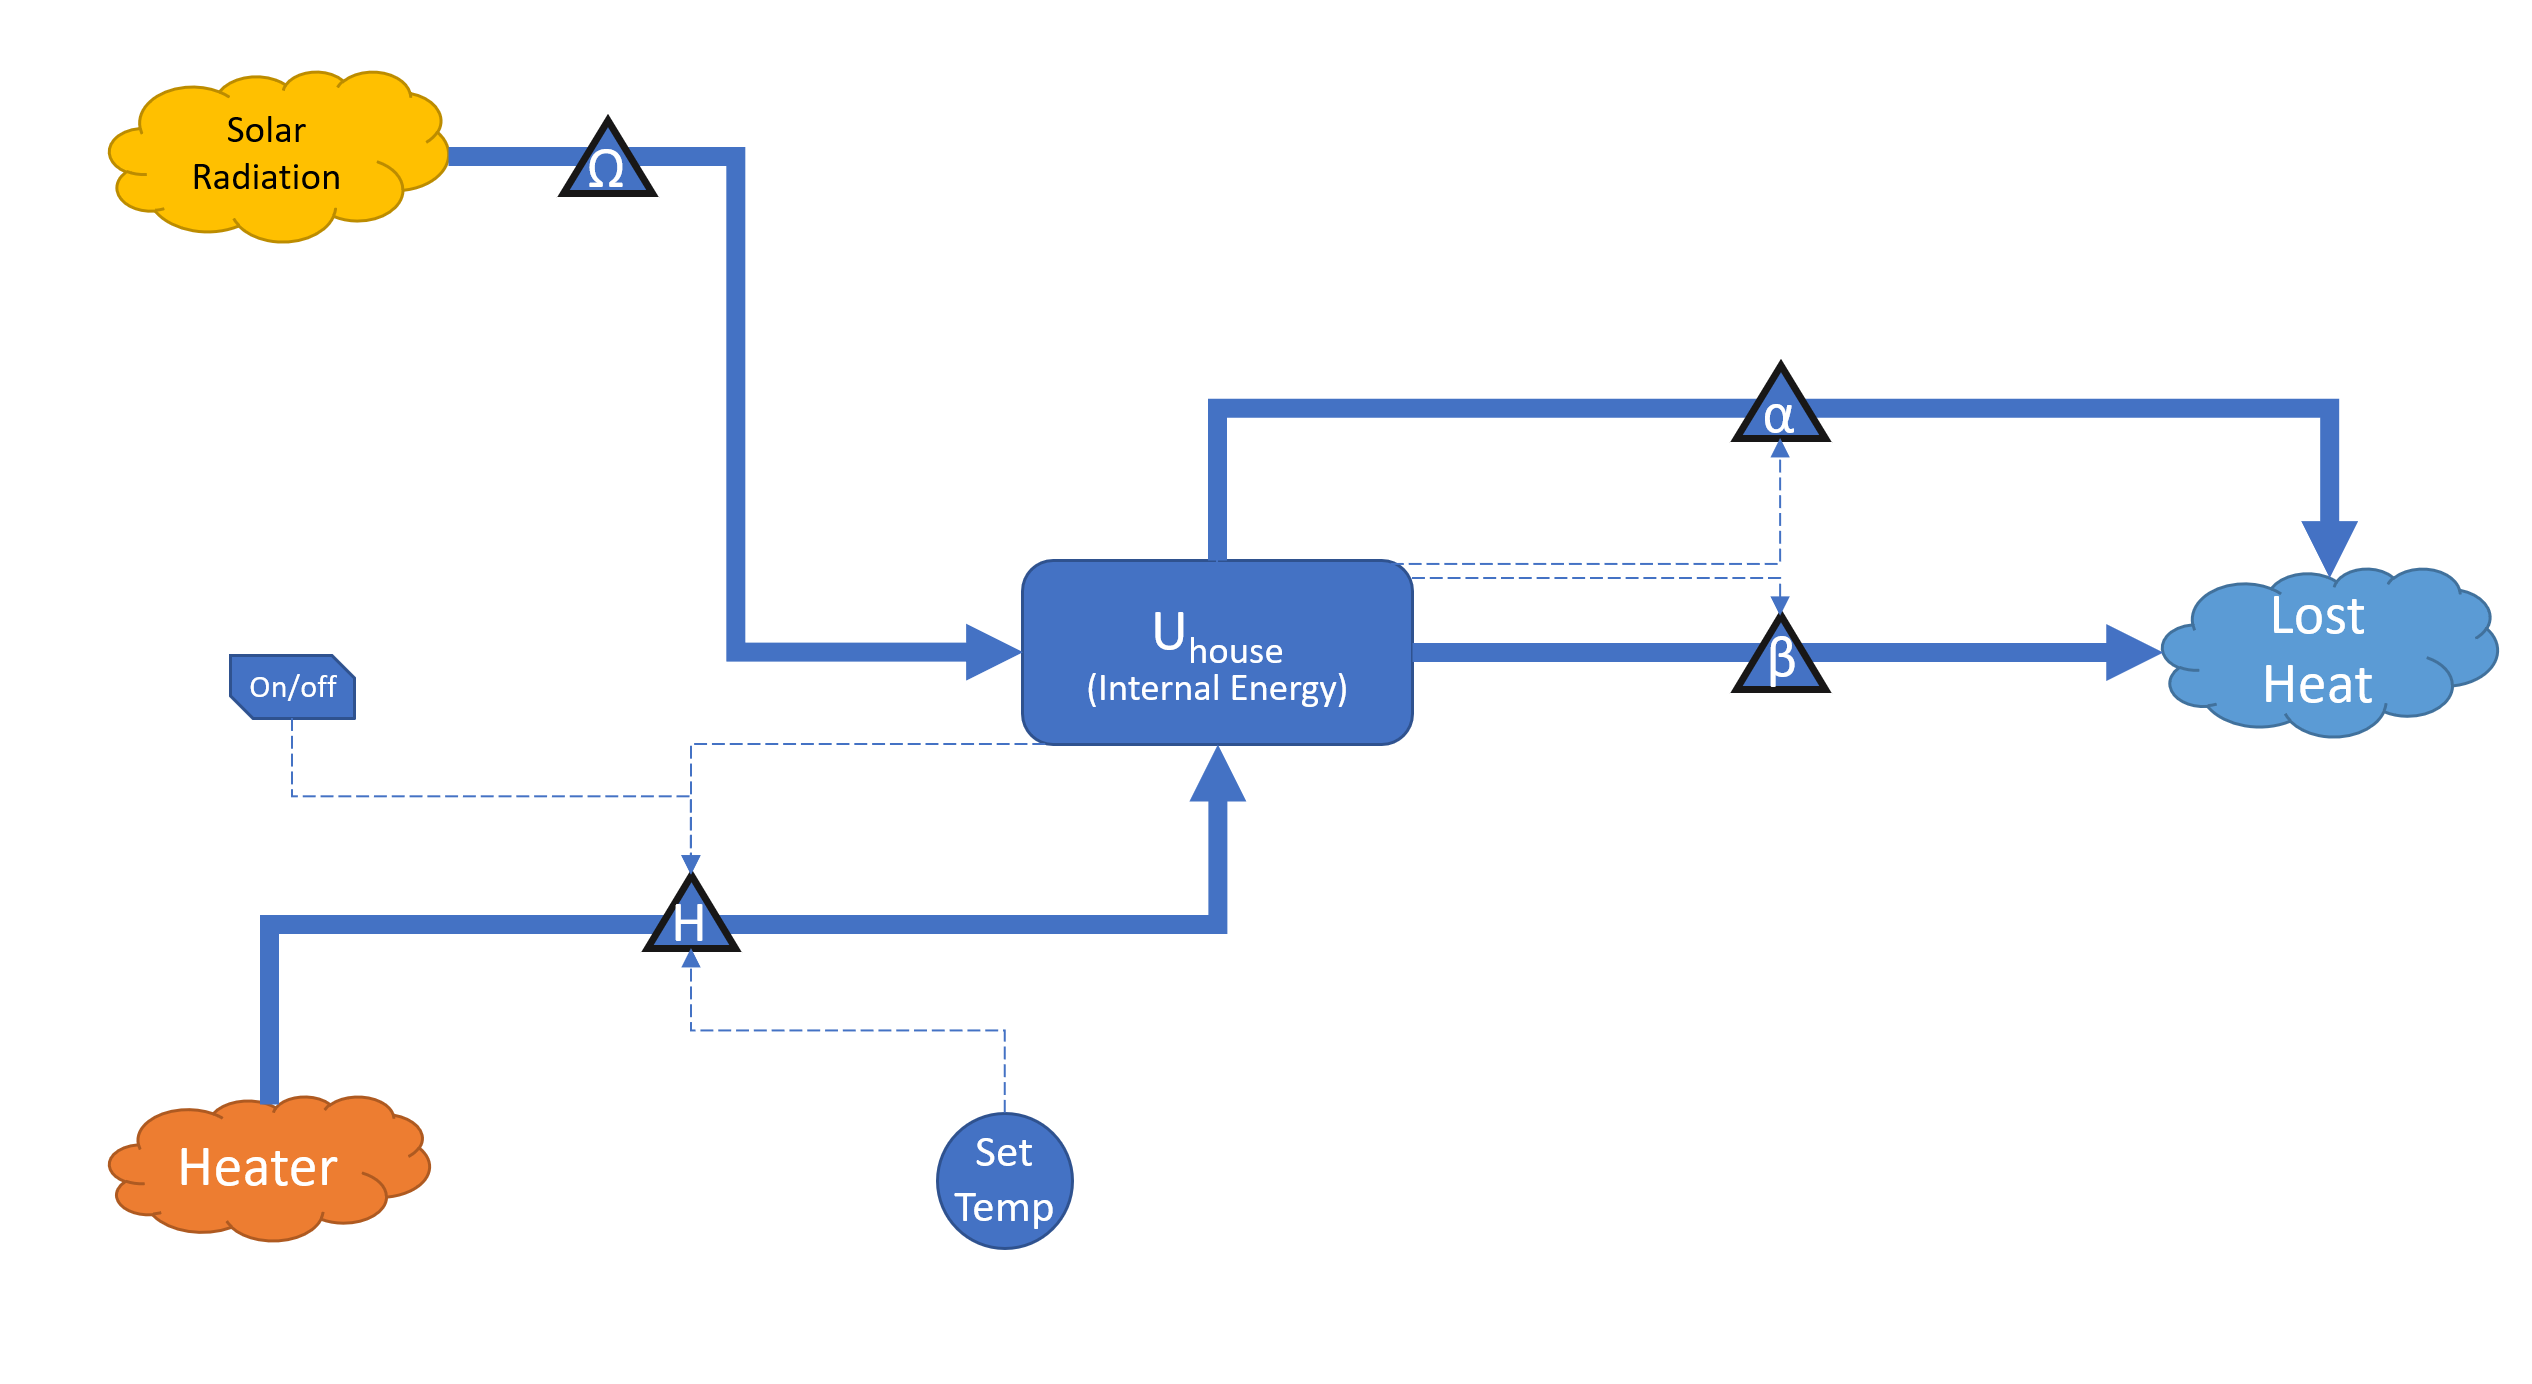

### Mathamatical Model

From the stock and flow diagram, the following differential equation is generated.


$$\frac{dU}{dt} = H\Phi  + \Omega  - \frac{\Delta T}{R_{tot}}$$


 Where:

- $U$ is the internal energy of the house

- $H$ is the wattage of the heater

- $\Phi$ is a logical value indicating if the heater is on or off

- $\Omega$ is the energy of the sun in Watts

- $\Delta T$ is the temperature difference between the house and the environment

- $R_{tot}$ is the total conductive resistivity of the house

To calculate if the heater is on or off ($\Phi$), the model uses a discrete “overshoot and undershoot control band” which is commonly found in household thermostats. This causes the temperature of the house to oscillate around the set temperature and allows the heater to turn on less frequently.

This control system will be maintained in both scenarios while the set temperature will be varied to reflect keeping the heater on vs. turning it off. A parameter sweep can then be carried out to probe the effects of the different parameters in the model and compare the efficiencies of the two scenarios.

To calculate the total energy ($E$) used by the heater in order to assess each scenario, the model also tracks $\frac{dE}{dt} = H\Phi$

### Assumptions

In the model, there are several assumptions that are made.  Firstly, the house being modeled is very simple and it does not contain any internal walls, furniture, appliance, etc. Therefore, the thermal mass of the house can only be a crude estimate.  However, because this generalization will affect both scenarios, the model should still make informative relative comparisons.

In addition, all the house’s internal energy is modeled by a single stock. In other words, we are assuming that the system is quasi static. This is reasonable because the rate at which the heater heats the air likely slower than the rate the air heats the solid material in the house. 

### **Verification and Validation**

To verify the implementation of the model, a test scenario was generated where the house is initially at the ambient temperature. The house set temperature is raised to 20 C for 6 hours, and then the set temperature is set to -20 C (bellow the ambient temperature) for 6 hours. 

set_temp_range = [293*ones(1,6*60*60), 283*ones(1,6*60*60)];
[time_range, temperature, energy_consumption, on_time] = house_cooling(set_temp_range);

house_height = 3

R_wall = 0.0094

A_tot = 300

R_value = 3.1415e-05

U_0 = 8.4412e+09

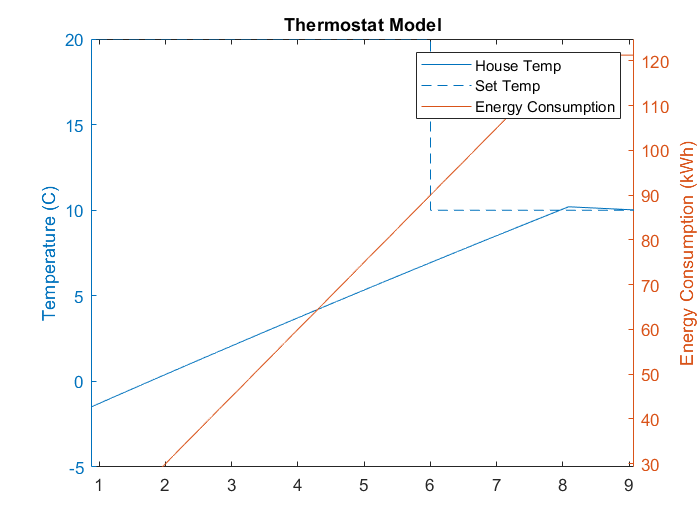


figure(1)
clf
title("Thermostat Model")


yyaxis left
hold on
plot(time_range / (60*60), temperature-273);
plot(time_range / (60*60), set_temp_range-273)
ylabel("Temperature (C)")
legend("House Temp", "Set Temp")
hold off

yyaxis right
plot(time_range / (60*60), energy_consumption / 3.6E6)
ylabel("Energy Consumption (kWh)")
legend("House Temp", "Set Temp", "Energy Consumption")

disp("Total on time: " + string(on_time / 60 / 60 + "hours"))

Total on time: 8.3436hours


## Results

## Interpretation

## Methodology

questions to consider

- what heating systems are there / how fast + energy efficient is the heating system

- house specifications

-     how big is the house

-     what kind of insulation

-     roof is flat, house is cube

- the outside world

-     ambient temperature + how it changes over the day

assumptions/things we are going to ignore

- the existence of night

- rooms - might affect the 

- in winter - ambient temperature always going to be colder

- convection is not significant enough of a energy loss that it needs to be modeled - lumping inside convection, walls conduction, outside convection

### Stocks

internal energy of the house

### Flows

flows in

- radiation from sun

- heating system (forced input)

-     amount of energy being used depends on the current temperature

flows out

- conduction

-     loss of heat through walls

-     loss of heat through door

-     loss of heat through windows

-     loss of heat through roof

### Parameters

- ideal temp: you want to have your house at x degrees C

- wattage heater

- solar radiation:

- thermal mass

- aperture

- envelope

### Defining our house

Our house is a cube with a flat roof

average sqft of a house in MA: 1,744 square feet = 162.022902 square meters

width = 10; % m
length = 15; % m
width*length % size of house in square meters

ans = 150

height = 3 % m, approx 10 ft

height = 3

% define thermal mass
% add windows

#### Stock and Flow


$$\frac{dU}{dt} = P_{heater} + P_{sun}  - \frac{\Delta T}{R_{tot}}$$


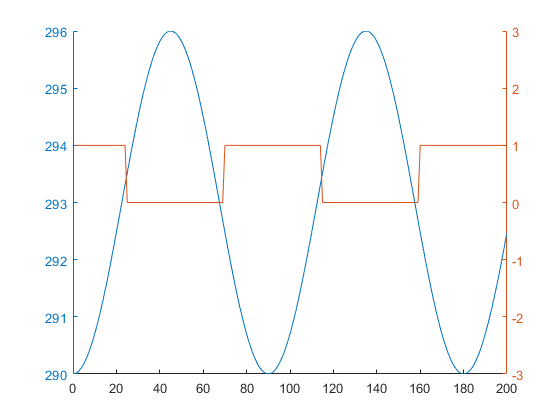

set_temp = 293;
t_0 = 293;
heater_state = false;

m = 10000; %kg
c = 920; %for concreat
H = 1000; %Watts
buffer = 1;

%verification of thermostat logic
temp = zeros(3, 200);

for i=1:200
    temp(1,i) = i;
    t = t_0+(3*cosd(4*i+180));
    heater_state = get_heater_state(t, set_temp, heater_state);
    temp(2,i) = t;
    temp(3,i) = get_heater_state(t, set_temp, heater_state);
end

%plot
clf
hold on
yyaxis left
plot(temp(1,:), temp(2,:))
yyaxis right
plot(temp(1,:), temp(3,:))
ylim([-3 3])
hold off

set_temp_range = [293*ones(1,6*60*60), 293*ones(1,6*60*60)];

[time_range, temperature, energy_consuption, on_time] = house_cooling(set_temp_range);

set_temp_range =    293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293   293


house_height = 3

R_wall = 0.0094

A_tot = 300

R_value = 3.1415e-05

U_0 = 8.4412e+09

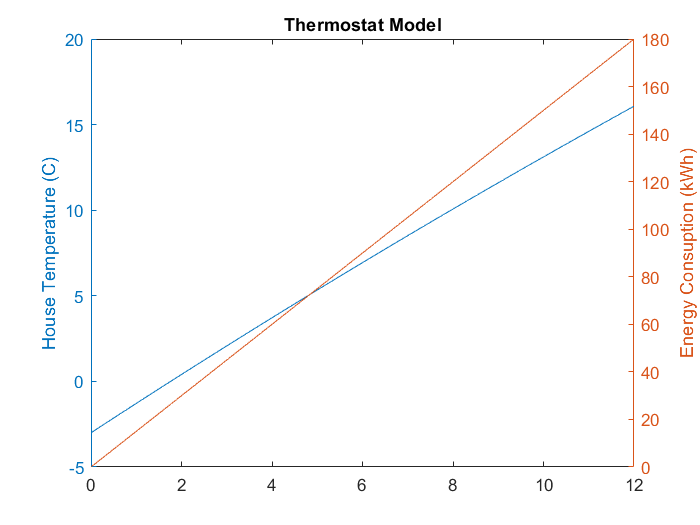


figure(1)
clf
title("Thermostat Model")
yyaxis left
plot(time_range / (60*60), temperature-273)
ylabel("House Temperature (C)")
yyaxis right
plot(time_range / (60*60), energy_consuption / 3.6E6)
ylabel("Energy Consuption (kWh)")

disp("Total on time: " + string(on_time / 60 / 60 + "hours"))

Total on time: 11.9997hours
